# Matrices

Matrices are very useful for many types of calculations, for example when solving certain types of differential equation, or in performing multivariate data analysis. For small matrices (e.g. matrices with 2 or 3 rows and columns) we can perform most matric manipulations using a pen and paper. However, we frequently have to deal with matrices that are far larger than this, for which calculation by hand is not a realistic option. Consequently we have to resort to numerical methods. 

## Matrix Multiplication

Matrix multiplication is a common operation that quickly becomes onerous and error-prone as the matrices incfrease in size. However, it's quite easy to write a small piece of code that performs the operation for you. we have done this in the function `MatrixMultMMEES`

% Some examples of matrix multiplication

a1 = [1 2; 3 4];
b1 = [4 3; 2 1];

a2 = [1 2 3 4; 5 6 7 8];
b2 = [10; 11; 12; 13];

a3 = [1 2; 3 4; 5 6];
b3 = [1 2 3; 4 5 6; 7 8 9];

c1 = MatrixMultMMEES(a1, b1)

c1 =      8     5
    20    13


c2 = MatrixMultMMEES(a2, b2)

c2 =    120
   304


%c3 = MatrixMultMMEES(a3, b3)

Runnig this code we find that the last example gives an error, as it should. 

Fortunatley, many modern prgramming languages such as Matlab have routines for performing basic matrix manipulations already built into them. Let's compare the performance of the routine we have just created with the built-in operation for matrix multiplication in Matlab. (*First, you should comment out the *`c3`* calculation above otherwise Matlab will halt the operation when you run the livescript)*

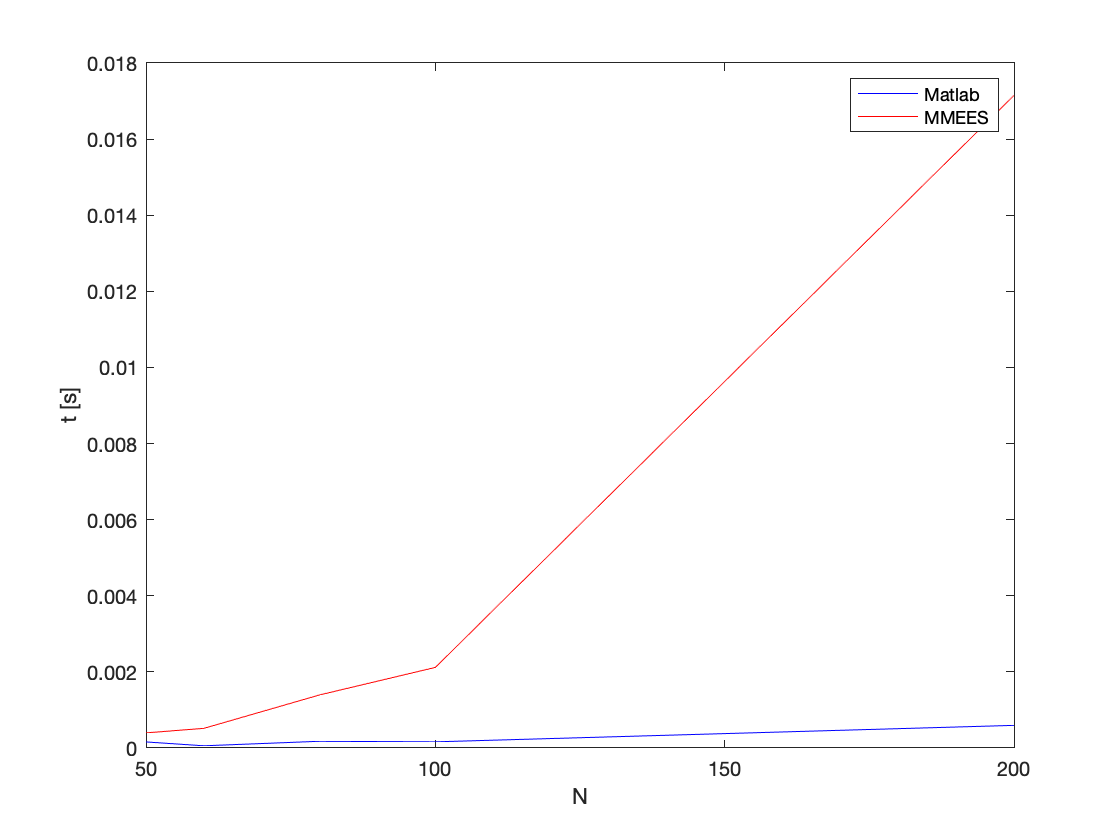

% Let's examine what happens when we multiply two large square matrices. 
N = [50 60 80 100 200];

% We initialize some storage for the run-times of the routines
t_mmees = zeros(length(N),1);
t_matlb = zeros(length(N),1);

% Now loop through the sizes of the matrices, creating new matrices and
% timing our multiplcation routine and the built-in Matlab one
for i_size = 1 : length(N)
    
    a = randn(N(i_size));
    b = randn(N(i_size));
    
    tic
    c = MatrixMultMMEES(a,b);
    t_mmees(i_size) = toc;
    
    tic 
    c = a*b;
    t_matlb(i_size) = toc;
    
end

figure(1)
plot(N, t_matlb, 'b', N, t_mmees, 'r')
xlabel('N')
ylabel('t [s]')
legend('Matlab', 'MMEES')

## The Matrix Inverse

Computer languages like Matlab also have built-in routines for calculating the determinant and inverse of a matrix. For a $(2\times 2)$matrix we have seen that calculating the inverse matrix is relaitively easy by hand. But again, as the size of the matrix increases, calculating the inverse on a computer becomes the better choice. 

% Set up a matrix
a = randn(2);

% Calculate the determinant of the matrix using Matlab's internal
% functions, and then use it to calculate the inverse matrix
det_a = det(a);
inv_a = [a(2,2) -a(1,2); -a(2,1) a(1,1)]/det_a

inv_a =    5.2295e-01   1.3293e+00
  -7.9014e-01   4.9858e-01



% Calculate the inverse directly within Matlab
inv_a_mat = inv(a)

inv_a_mat =    5.2295e-01   1.3293e+00
  -7.9014e-01   4.9858e-01


To calculate larger matrices, it's better to use the Matlab built-in routines.

b = randn(10);
inv_b = inv(b)

inv_b =    2.4267e-01   4.5179e-01   3.1353e-01   2.7859e-01  -3.9128e-01  -1.2289e-01   1.1108e-01   1.4735e-01  -3.7192e-01   1.7981e-01
   3.6307e-01   4.0899e-01  -7.1081e-02   5.5556e-01  -9.0801e-02   1.6179e-01   5.8072e-01   1.5095e-01   2.5526e-01   2.0774e-02
   5.0875e-01  -4.6493e-01  -4.9433e-01   2.6750e-01   7.4011e-01   3.7726e-01  -6.4170e-01  -1.7191e-03   2.1877e-01  -7.2711e-01
   1.0607e+00  -3.1034e+00  -2.1391e+00   1.3423e+00   3.7729e+00   2.5938e-01  -2.9366e+00  -8.6780e-01   1.0392e+00  -3.7689e+00
   5.3849e-01  -1.7987e+00  -1.2505e+00  -4.7707e-02   1.8608e+00   5.7030e-01  -1.1692e+00  -3.4580e-01   4.2846e-01  -1.1572e+00
   7.4870e-01  -6.8250e-02  -5.1149e-01   1.7023e+00   9.7088e-01   7.8879e-01   5.3793e-02   4.8455e-02   9.1986e-01  -3.1046e-01
  -2.0373e-01  -4.5044e-01  -5.1355e-02  -7.8516e-01  -2.5527e-03   1.5009e-02  -1.4794e-01  -2.2328e-01  -3.1369e-01  -1.7813e-01
   2.6321e-01  -1.0221e+00  -6.5130e-01  -9.1343e-02   1.3226e+00   5.9367e

## Gaussian Elimination

Processes like Gaussian Elimination are algorithmic and so are well-suited to being performed by a computer. It's instructive to write our own code to start with, but be warned, solving large systems of linear equations numerically is not easy and a great deal of thought has gone into developing sophisticated computer codes that can do this safely (i.e. without returning crazy, incorrect answers). 

% Here is an example of a straightforward, but quite bad, way of coding up
% Gaussian Elimination

a = [1 2 3; 4 5 6; 7 8 9];

[n_rows, c_cols] = size(a);

b = a;

for i_row = 1 : n_rows-1
    for j_indx = i_row+1 : n_rows
        b(j_indx,:) = b(j_indx,:) - b(j_indx,i_row)/b(i_row,i_row)*b(i_row,:);
    end
end

b

b =      1     2     3
     0    -3    -6
     0     0     0


This is not a great way to do this for many reasons. For one thing there's the possibility that `b(i_row,i_row)` might be zero, in which case we would get a value that is undefined. Even if `b(i_row,i_row)` is very close to zero, we may run into problems. Fortunately, Matlab has a buitl-in routine for calculating the reduced row-echelon form of a matrix using Gauss Jordan elimination (the function `rref`). However, in most cases we are interested in calculating the inverse of a matrix in order to solve a set of linear equations and once again, Matlab's built-in functions come to the rescue. To see how this works, let's solve the following system of linear equations


$$3x + 2y + 5z = 9.3,\qquad x - y + 2z = -2.1,\qquad x + 2y - z = 7.5$$


A = [3 2 5; 1 -1 2; 1 2 -1];
b = [9.3; -2.1; 7.5];

x = A\b

x =    1.2000e+00
   3.1000e+00
  -1.0000e-01


The backslash operator in Matlab solves a system of linear equations using Gaussian elimination. We could also have solved this system by calculating the inverse of A 

x2 = inv(A)*b

x2 =    1.2000e+00
   3.1000e+00
  -1.0000e-01


However, for larger matrices this is not a good idea because, as explained in Chapter 2, it takes more computer operations and so is less efficient. 

A = magic(10);  % Create a "Magic" matrix of size 10x10
B = eye(10);    % Create the 10x10 unit matrix
  
tic
C = inv(A);     % Calculate the inverse of A

t_inv = toc;

tic 
C = A\B;        % Since B is the unit matrix, this will calculate the inverse of A

t_bckslsh = toc;

disp(['Inverse Calculation takes ' num2str(t_inv) ' s and the Backslash operator takes ' num2str(t_bckslsh) ' s'])

Inverse Calculation takes 0.0080705 s and the Backslash operator takes 0.0058421 s


For the examples above you may get a warning that matrix is close to singular (i.e. the determinant is almost zero) and we know that will produce a problem. So let's investigate things with a different matrix and see what happens if we gradually increase the size of the matrix from a 2x2 matrix upwards — you might be tempted to try using a very large matrix, but you should be warned that doing so will slow down your computer a great deal and may take a long time to run, so don't use a maximum size much larger than about 10. Note that the way we calculate the size of the matrix is to calculate $2^n$ where n is an integer from 1 to 10. That means that the largest matrix we are calculating below has $2^{10}=1024$ rows and columns!!

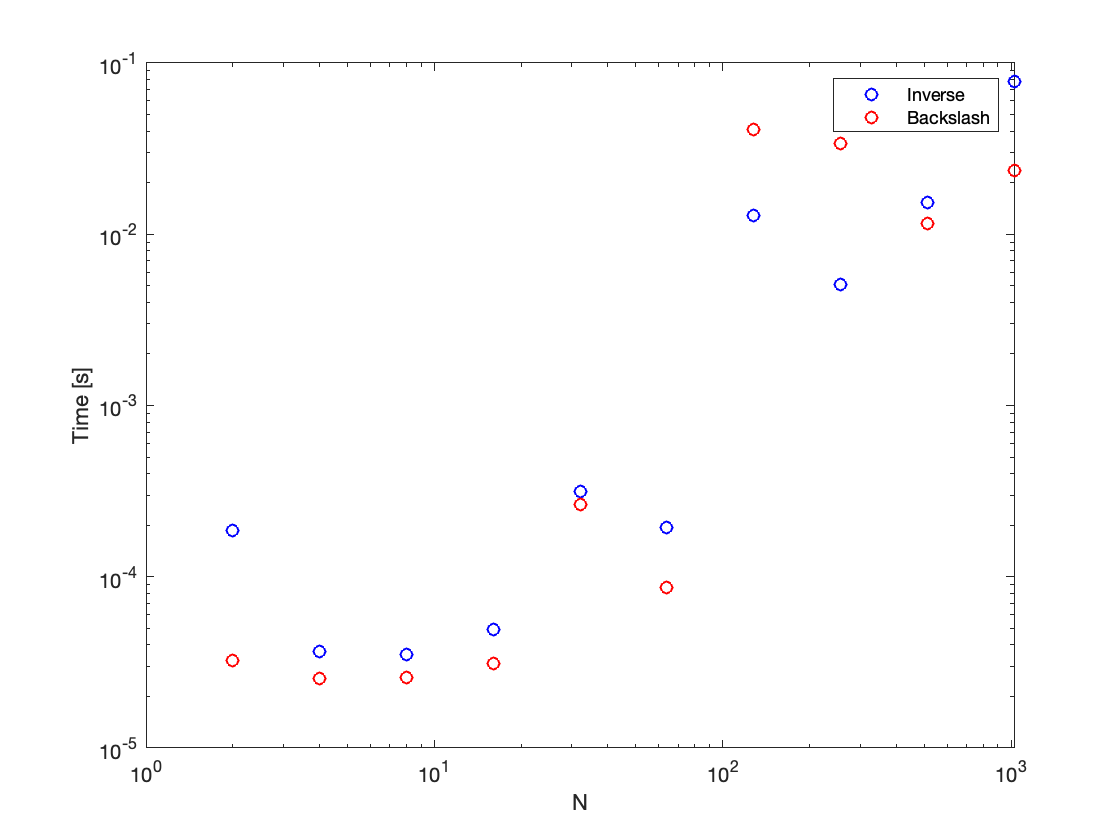

% Define the maximum size of the matrix: DO NOT MAKE THIS MUCH BIGGER THAN
% 10!
max_size  = 10;

% Create preallocated storage for the times and matrix size. 
t_inv     = zeros(max_size,1);
t_bckslsh = zeros(max_size,1);
n_size    = zeros(max_size,1);

% Loop through the sizes and calculate th inverses of the matrices
for i_row = 1 : max_size
    
    n_size(i_row)  = 2^i_row;   % The size of the square matrix
    
    A = randn(2^i_row);         % Create a square matrix with random entries
    B = randn(2^i_row,1);       % Create a vector of random entries
    
    % Solve the linear system by calculating the inverse
    tic
    x1 = inv(A)*B;
    t_inv(i_row) = toc;
    
    % Solve the linear system using Gaussian elimination
    tic
    x1 = A\B;
    t_bckslsh(i_row) = toc;
    
end

figure(2)
loglog(n_size, t_inv, 'bo', n_size, t_bckslsh, 'ro')
xlabel('N')
ylabel('Time [s]')
legend('Inverse', 'Backslash')

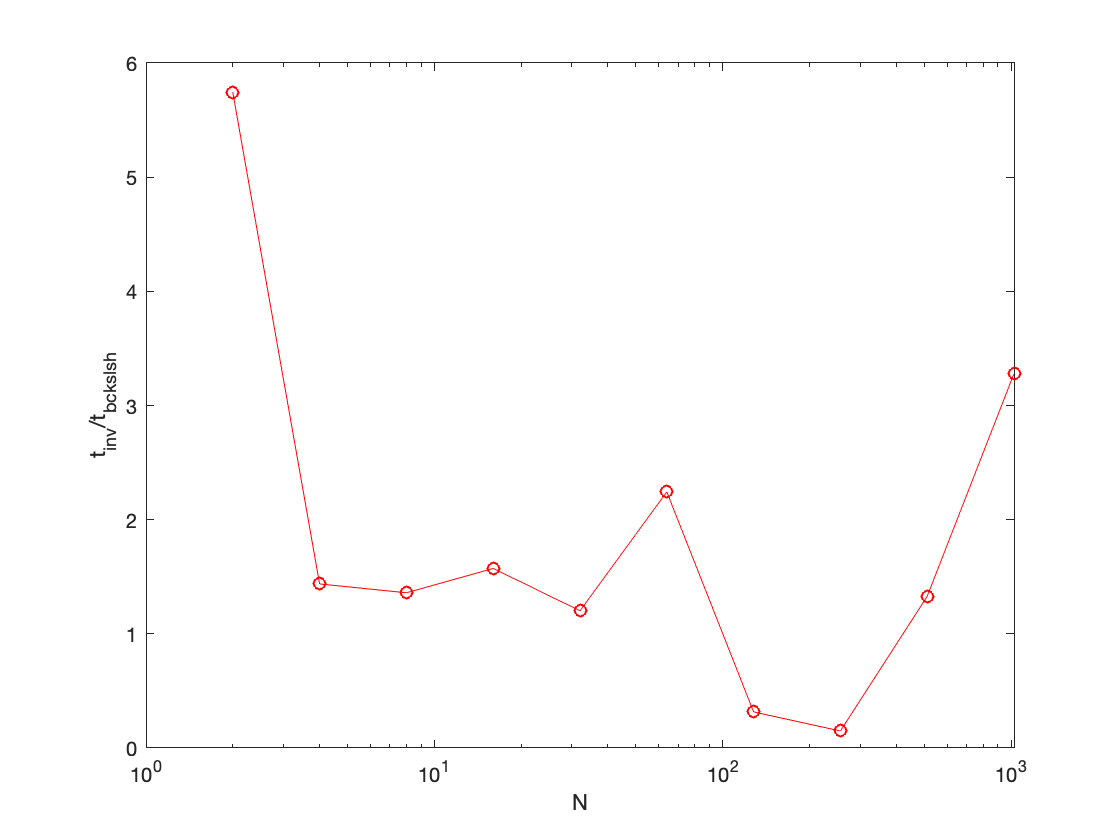

figure(3)
semilogx(n_size, t_inv./t_bckslsh, 'ro-')
xlabel('N')
ylabel('t_{inv}/t_{bckslsh}')

We can see from the plot that in general solving the system using the back-slash operator is several times faster than solving the system by calculaing the inverse matrix first. 